# **ベンチマークモデルの使用（IEEE68busモデル）**

## ・モデル概要

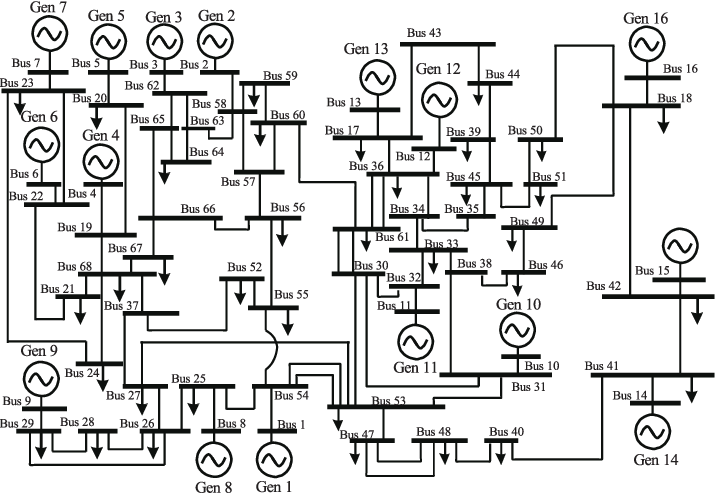

## ・実装方法

 

net = network_IEEE68bus();

# **ベンチマークモデルの使用（IEEE9busモデル）**

## ・モデル概要

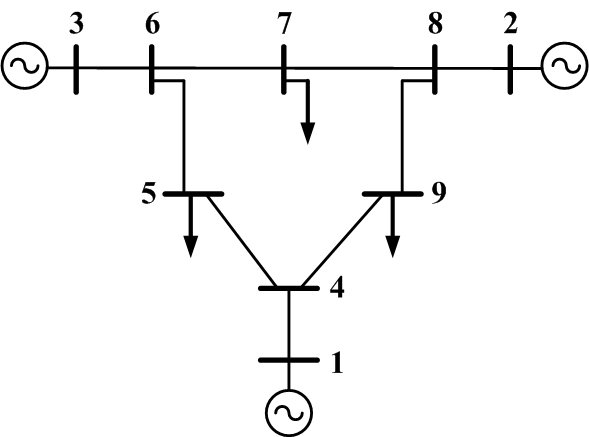

## ・実装方法

net = network_IEEE9bus();

# **新しいモデルの定義**

## **1. power_networkクラスの定義**

では、まず電力系統モデルの大枠となる`power_network`クラスを定義します。このクラスには、各母線やブランチ、機器などの情報を整理して格納しておく`properties`と、それらのデータを用いてシミュレーション等の解析を行う`method`が定義されています。この大枠に以下ではデータを代入します。

`power_network`クラスの定義は簡単で以下のように実行するだけです。

net = power_network();

## **2. busクラスの定義 >> power_networkクラスへの付加**

次に、母線の種類（PV,PQ,slack）と各母線の潮流設定の値を決定します。

今回は以下のように設定してみます。

表中のP、Q、|V|、∠V はそれぞれ「有効電力」「無効電力」「母線電圧の大きさ」「電圧の偏角」を指しています。母線の種類や潮流設定の各パラメータの意味に関しては[「電力ネットワークの解説ページ」](https://guilda-dev.github.io/guilda-doc/aboutPowerSystem/0TopPage/)を参考にして下さい。

**GUILDA上での実装方法**

母線の定義についても、送電線の定義と同様にbusクラスの変数を定義し、power_networkクラスのadd_busというmethodを用いて代入します。また、busクラスにはbus_PV、bus_PQ、bus_slackという子クラスが定義されており各母線の種類ごとにこれらを使い分けて定義します。

- slack母線の場合:

- PV母線の場合:

- PQ母線の場合:

各関数の引数については「[電力系統モデルの作成ページ](https://guilda-dev.github.io/guilda-doc/Reference/defineNet/NewPowerNetwork/)」を参照してください。それでは、実際に各母線の情報を定義していきます。

shunt = [0,0];
%母線1の定義
bus_1 = bus_slack(2,0,shunt);
net.add_bus(bus_1);
%母線2の定義
bus_2 = bus_PV(0.5,2,shunt);
net.add_bus(bus_2);
%母線3の定義
bus_3 = bus_PQ(-3,0,shunt);
net.add_bus(bus_3);

## **3. componentクラスの定義 >> busクラスへの付加**

次に今回実装する3busモデルの各母線に付加する機器を決めます。今回のモデルでは母線1と母線2が発電機バス(slack母線とPV母線)、母線3が負荷母線(PQ母線)となっています。また、今回の実行例では、発電機母線に接続するのは同期発電機の1軸モデル、負荷母線に接続するのは定インピーダンスモデルの負荷とします。同期発電機の1軸モデルは下式のようになっています。

同期発電機モデルを適応する場合は、上式の各パラメータを決定する必要があります。以上の情報をまとめると下の表のようになります。

なお、同期発電機のパラメータの内、MATLABに実装できる変数名の制約により、そのまま書けない変数名は以下のように書き換えて表現しています。

**GUILDA上への実装方法**

機器の定義についても、母線の定義と同様にcomponentクラスの変数を定義し、それを系統に代入します。ただ、機器の定義は、送電網や母線のようにpower_networkクラスに代入するのではなく、power_networkクラスに代入されている、busクラスに代入します。機器は各母線ごとに接続されているためです。

また、同期発電機の1軸モデルはgenerator_1axisというクラスで定義されています。また定インピーダンスモデルはload_impedanceというクラスで定義しています。それでは実際に系統に機器モデルを代入していきます。

%系統周波数の定義
omega0 = 60*2*pi;

%母線1に同期発電機の1軸モデルを付加
Xd = 1.569; Xd_p = 0.963; Xq = 0.963; Td_p = 5.14; M = 100; D = 10;
mac_data = table(Xd,Xd_p,Xq,Td_p,M,D);
component1 = generator_1axis( omega0, mac_data);

net.a_bus{1}.set_component(component1);

%母線2にも同期発電機の1軸モデルを付加
Xd = 1.220; Xd_p = 0.667; Xq = 0.667; Td_p = 8.97; M = 12; D = 10;
mac_data = table(Xd,Xd_p,Xq,Td_p,M,D);
comp2 = generator_1axis( omega0, mac_data);
net.a_bus{2}.set_component(comp2);

%母線3には定インピーダンスモデルを付加
comp3 = load_impedance();
net.a_bus{3}.set_component(comp3);


ここでの注意点は、generator_1axisの引数のtable型変数の定義についてです。generator_1axisは引数で与えられたテーブル型の変数から、対応する列名の値を抽出していいるため、各パラメータの変数名はコード例と同じになるようにしてください。

## **4. branchクラスの定義 >> power_networkクラスへの付加**

次に送電線(ブランチ)の情報を整理します。GUILDAでは送電線の種類として、π型回路モデルの送電線(branch_piクラス)と、さらに位相調整変圧器も含む送電線(branch_pi_transferクラス)の2種類を実装しています。今回は送電線上に位相調整変圧器は含まれないと仮定します。

実装するモデルには「母線1-母線2」と「母線2-母線3」の２本の送電線が存在します。それぞれの送電線上のインピーダンスと対地静電容量の値は以下とします。

**GUILDA上への実装方法**

送電網の定義手順は、以下のようになります。

- 送電網の情報を代入したbranchクラスの変数を各送電網ごとに定義する。定義方法：branch_pi(from,to,[xreal,ximag],b);

- from , to : 送電線が繋ぐ母線番号

- xreal, x_imag : インピーダンスの実部、虚部

- b : 対地静電容量

- 生成したbranchクラスの変数をpower_networkクラスのadd_branchというmethodを用いて代入する。

では実際に代入しましょう。

%母線1と母線2を繋ぐ送電線の定義
branch12 = branch_pi(1,2,[0.010,0.085],0);
net.add_branch(branch12);
%母線2と母線3を繋ぐ送電線の定義
branch23 = branch_pi(2,3,[0.017,0.092],0);
net.add_branch(branch23);

## **5. 初期化処理（潮流計算の実行・平衡点の計算）**

net.initialize;

と実行します。これはpower_networkクラス内に定義されたinitializeというmethodを実行しており、プロパティに代入されたパラメータから潮流計算を行い、系統全体のシステムの平衡点を計算し、各値を新たなプロパティとして保存する関数です。これらの値はワークスペースから閲覧することができます。各パラメータの見方は、「[power_networkクラスのデータ構造](https://guilda-dev.github.io/guilda-doc/SourceCode/NetProperties/)」のページを参考にしてください。

# **制御器の付加**

% IEEE68busモデルを使用
net = network.IEEE68bus;

% AGCを定義
con = controller.broadcast_PI_AGC(net,1:16,1:16,-5,-500);

% 制御器を付加する
net.add_controller_global(con);

% シミュレーション
out = net.simulate([0,5],'fault',{{[1,1.01],1}});